## Polar Overturning Conceptual Model

#### Live script to run experiments and produce the figures.

#### twnh Aug, Sep '19, Jan–May '20, Sep '20, Oct '23

Must cd to the working directory to run the notebook. The notebook writes pdf figures to the figures directory. Crop them to make publication-ready figures.

Housekeeping:

clear
clear plot_POC_TS_diagram  % Clears persistent variables from this function.
close all
clc
%parpool('MJSProfile1',84) 
if(isempty(gcp))
    %parpool('MJSProfile1',84)
    parpool('local',16) 
end

Exp 1b: Northern hemisphere Fram Strait/Barents Sea Opening with updated parameters from Tsubouchi et al. (2023).

model1 = build_POC_model('NH_FSBSO_can_Oct23') ;

 Solutions for experiment: [Exp.~1 Fram Strait+BSO] with file suffices: [NH_FSBSO_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      3.4000          |           35.0000          |            4.7500
 Atlantic Water to shelf:             3.4000          |           35.0000          |   0.1028   0.2689   0.6421
 Polar    Water:                     -1.8675          |           34.3235          |  -1.7039  -1.0863  -0.0000
 Overflow Water:             1.2043   1.4288   1.5674 |  34.9022  34.9549  35.0714 |  -4.7261  -3.6699  -3.0705
 Shelf    Water:            -1.9941  -2.0607  -2.2015 |  36.4907  37.6234  40.0000 |  -0.5902  -0.2291  -0.0747
 Ambient

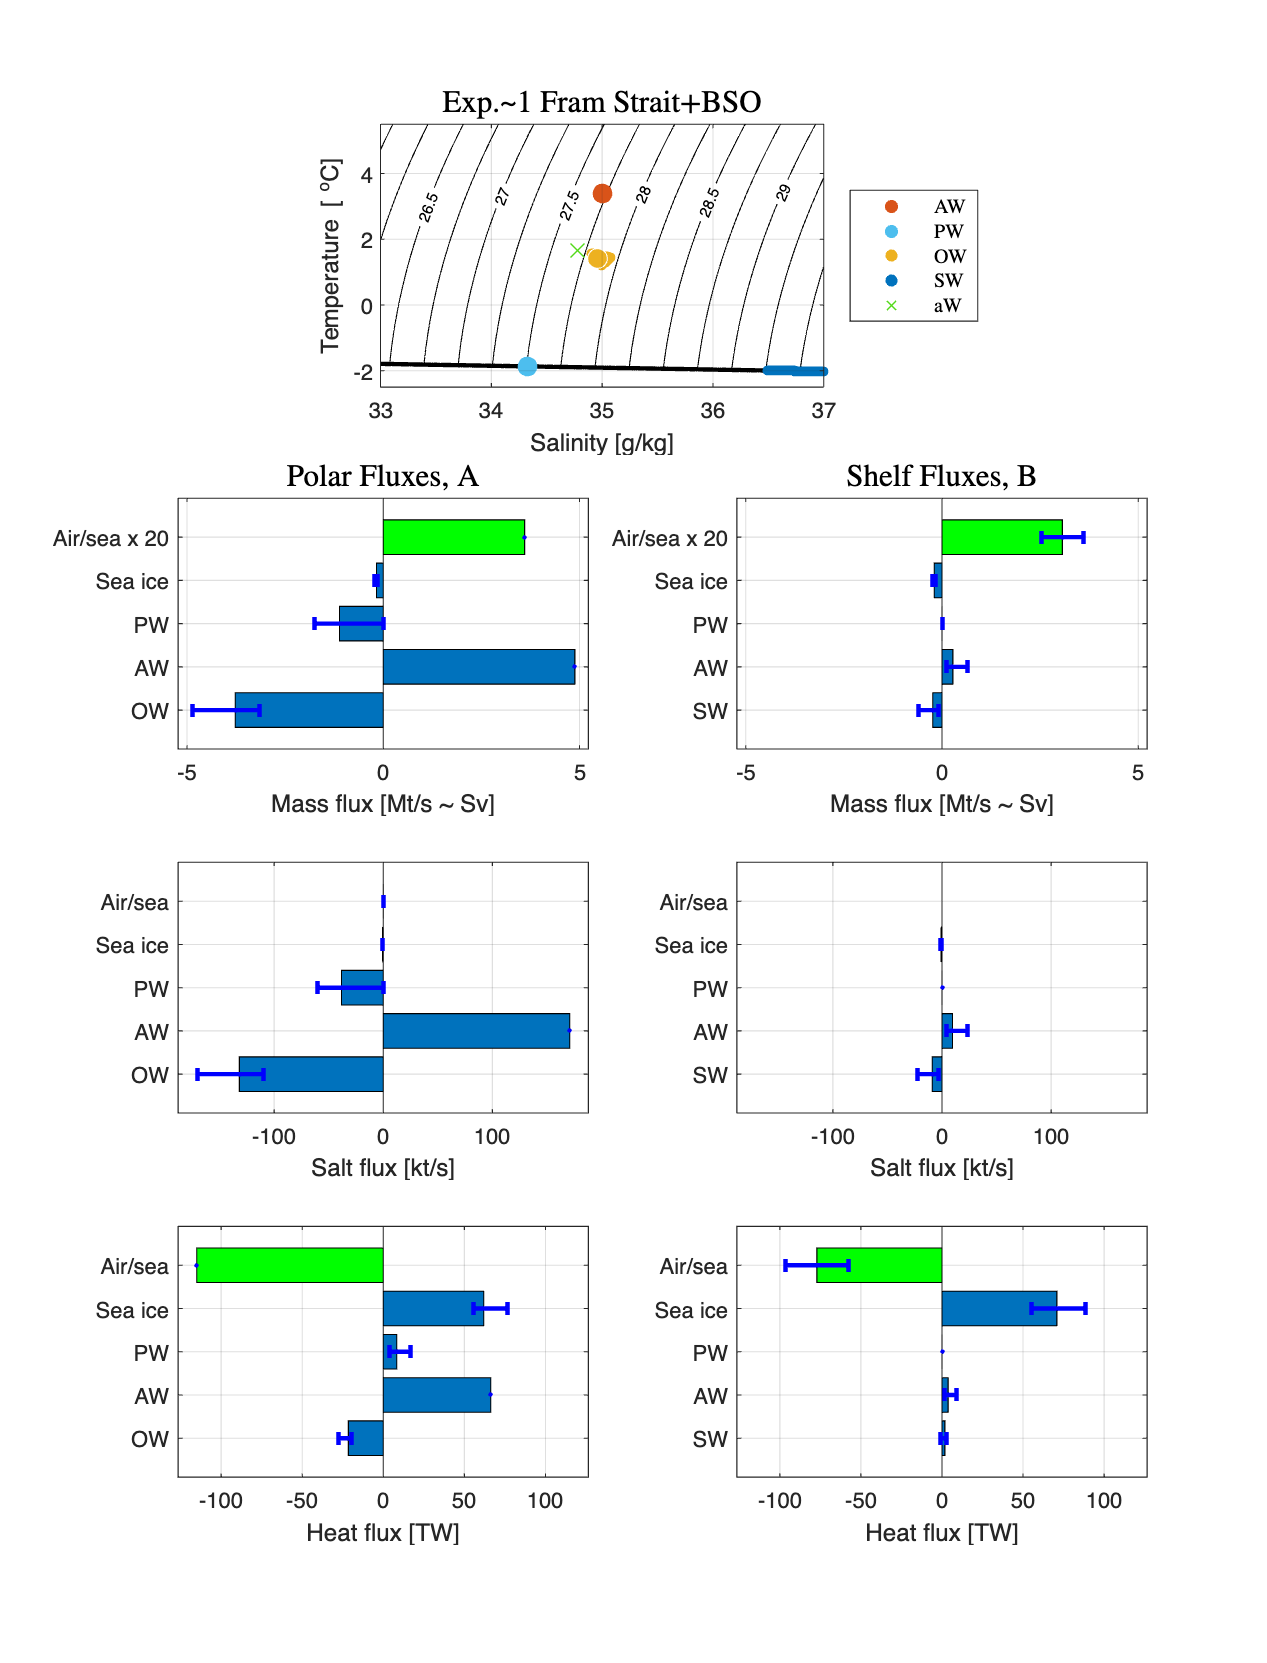

plot_POC_solution(model1)

Exp G1: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM).

modelG1 = build_POC_model('NH_FSBSO_LGM_can') ;

 Solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   4.4272   4.5250   4.5560
 Polar    Water:                     -1.9481          |           35.7064          |  -0.3128  -0.1229  -0.0100
 Overflow Water:            -1.9693  -1.9174  -1.8613 |  36.0681  36.0739  36.0864 |  -4.7239  -4.6132  -4.4256
 Shelf    Water:            -1.9693  -1.9698  -1.9708 |  36.0689  36.0771  36.0934 |  -4.5392  -4.5095  

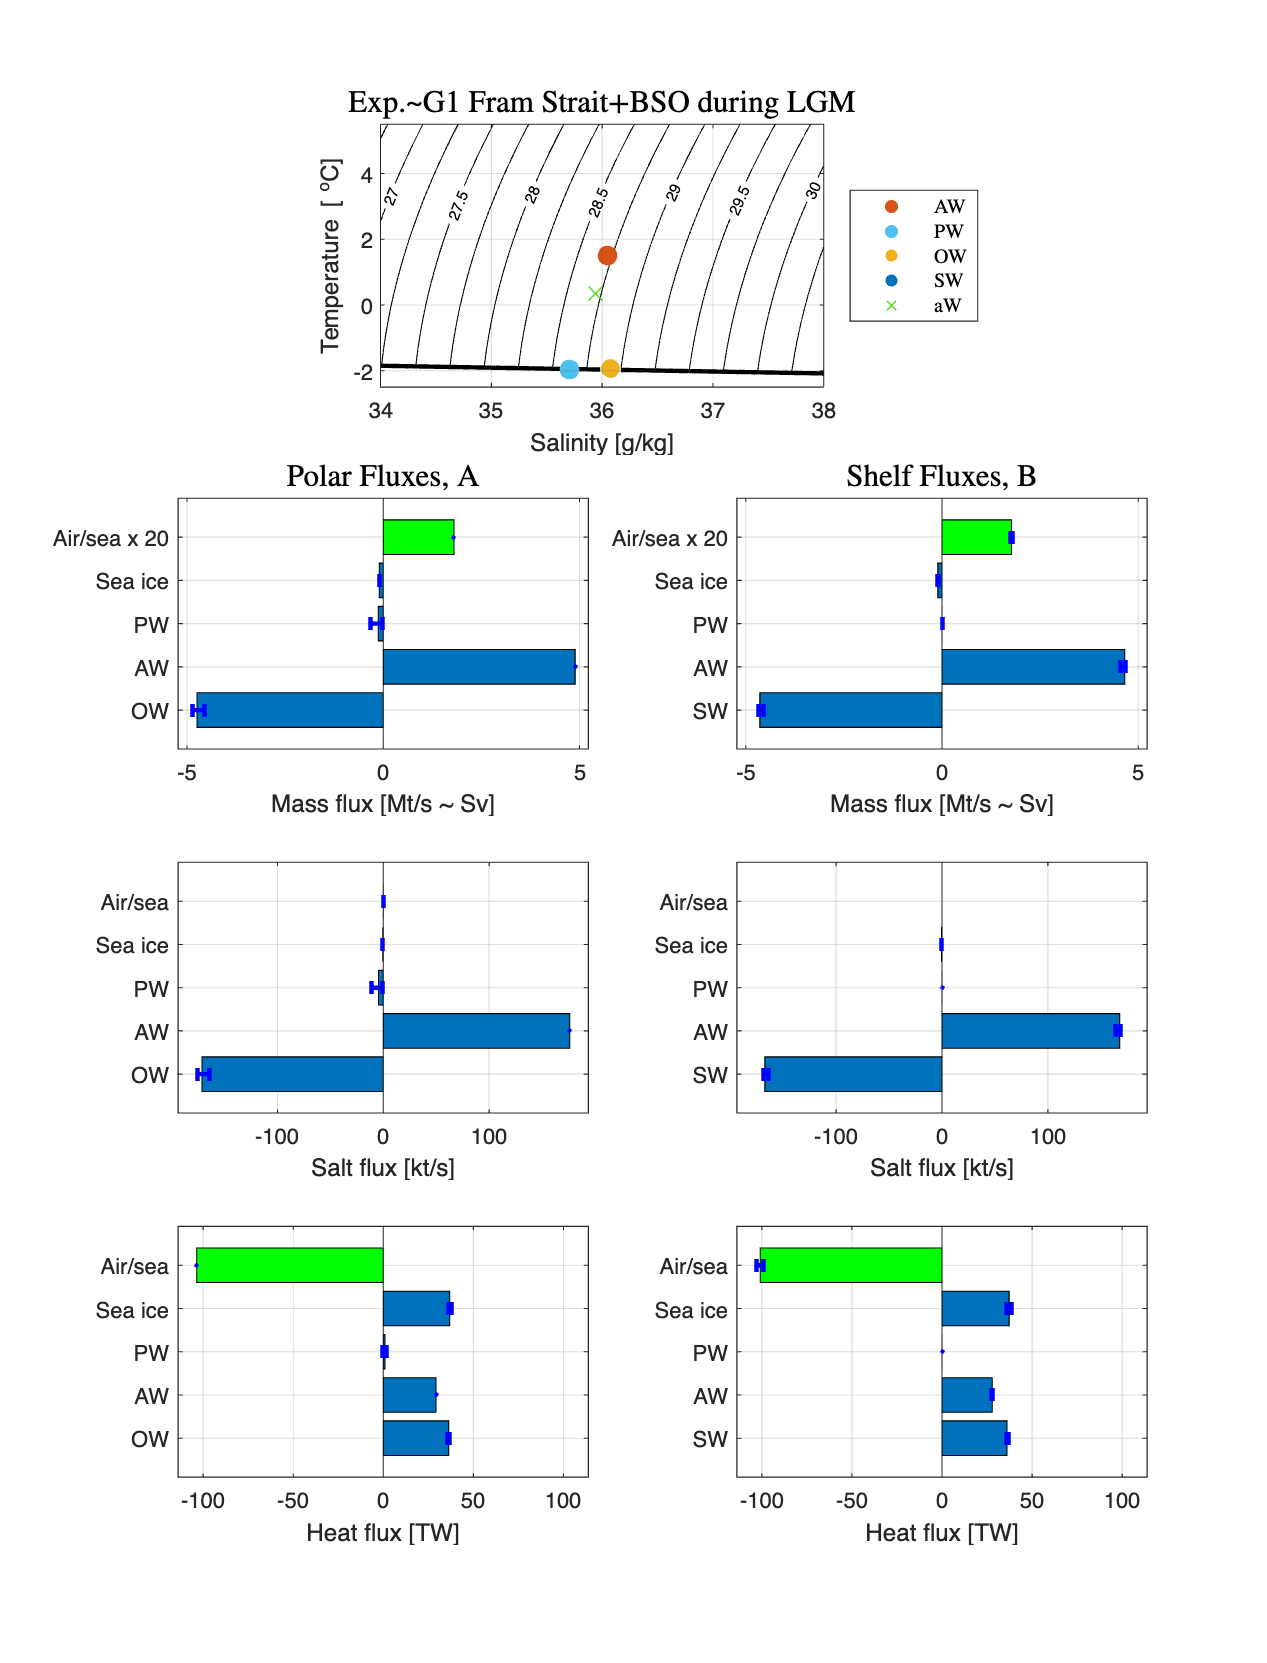

plot_POC_solution(modelG1)

modelG1 = build_stable_isotope_model(modelG1) ;

 Stable isotope solutions for experiment: [Exp.~G1 Fram Strait+BSO during LGM] with file suffices: [NH_FSBSO_LGM_can]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           2000.15 to  2000.15  |     -0.15 to    -0.15          
 Overflow Water:           1999.34 to  1999.34  |     -0.55 to    -0.55          
 Sea ice:                  1999.32 to  1999.32  |     -0.56 to    -0.56           
 Shelf    Water:           1999.32 to  1999.32  |     -0.56 to    -0.56           



Exp G1b: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with warm AW.

modelG1b = build_POC_model('NH_FSBSO_LGM_hiT1') ;

 Solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      4.0000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             4.0000          |           36.0500          |   0.8089   1.3741   2.2538
 Polar    Water:                     -1.9189          |           35.2049          |  -3.2392  -2.0747  -0.0101
 Overflow Water:            -0.0265   0.0374   0.1891 |  35.7822  35.8431  35.9223 |  -4.7471  -2.7369  -1.5988
 Shelf    Water:            -1.9532  -1.9603  -1.9711 |  35.7925  35.9147  36.0980 |  -2.

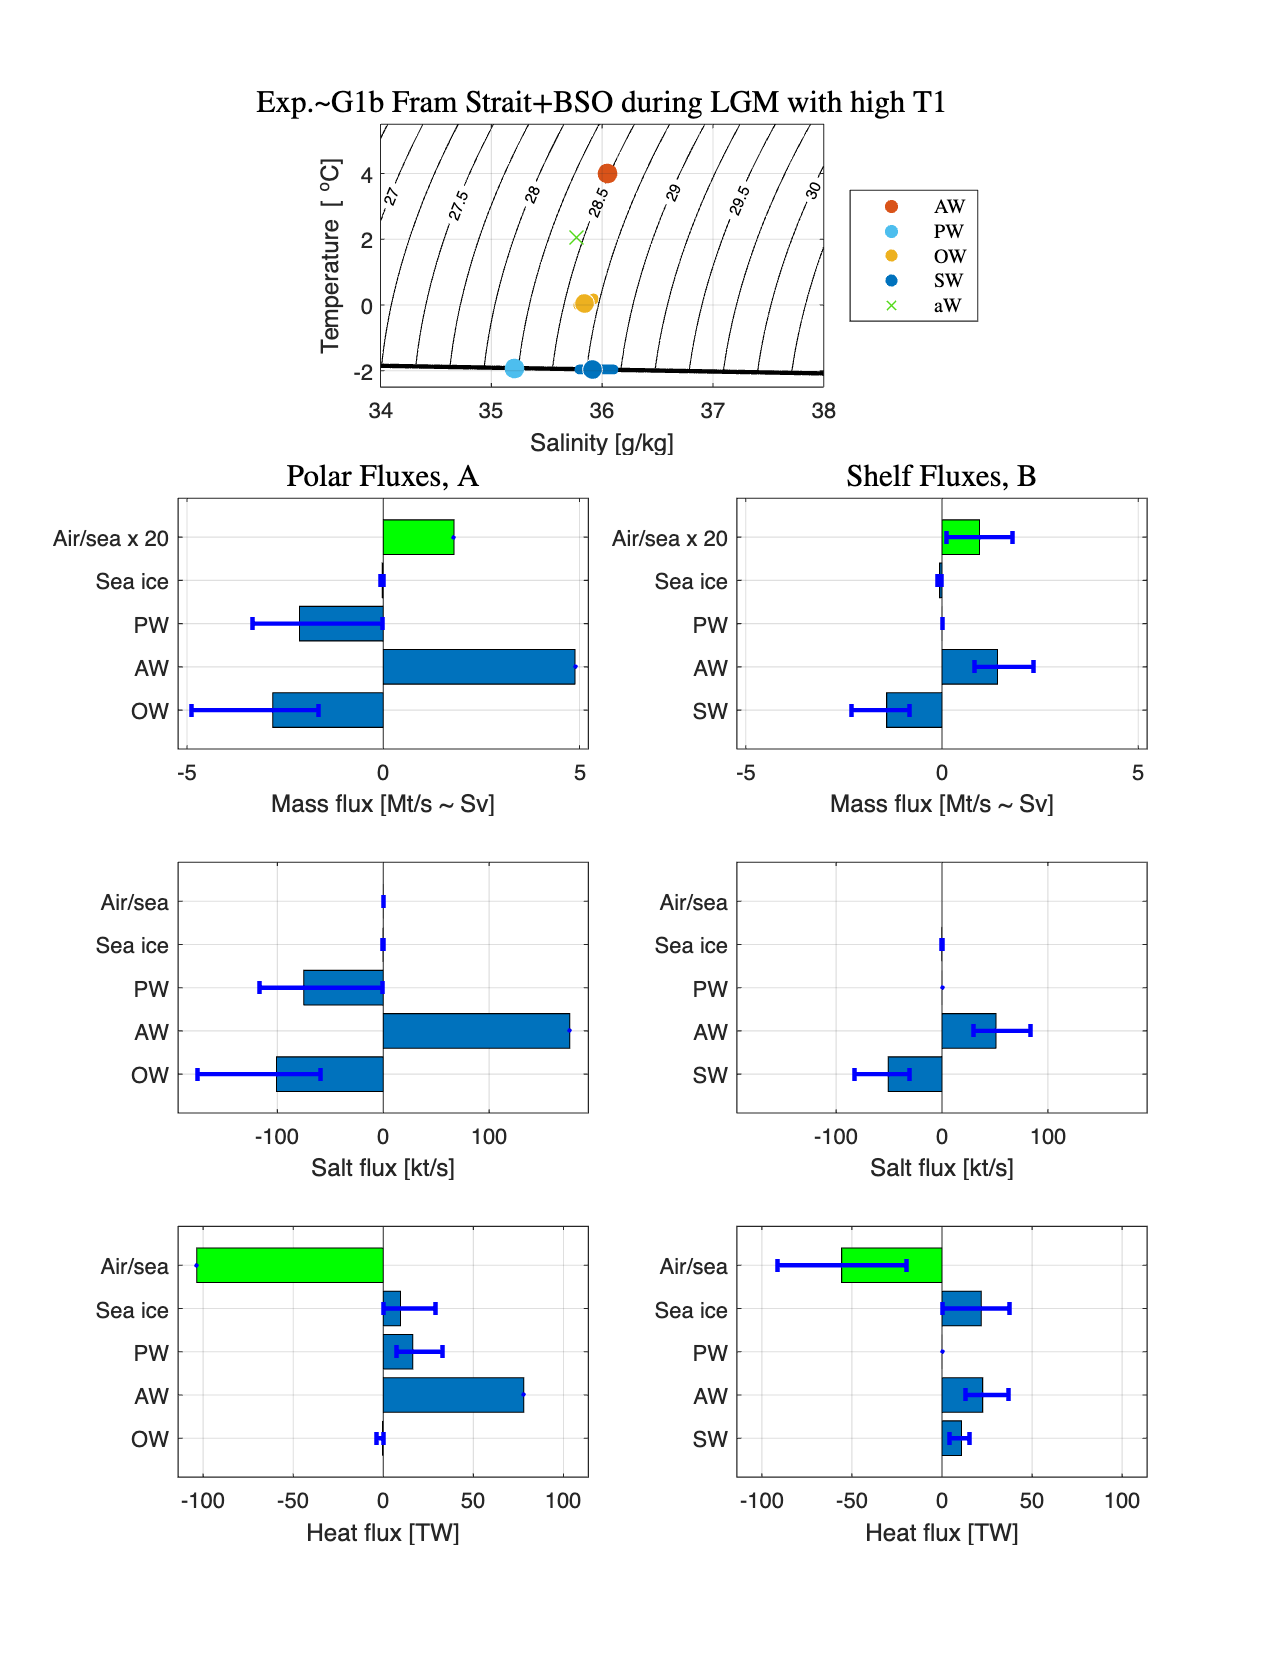

plot_POC_solution(modelG1b)

modelG1b = build_stable_isotope_model(modelG1b) ;

 Stable isotope solutions for experiment: [Exp.~G1b Fram Strait+BSO during LGM with high T1] with file suffices: [NH_FSBSO_LGM_hiT1]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           1999.71 to  1999.71  |     -0.37 to    -0.37          
 Overflow Water:           1999.11 to  1999.11  |     -0.67 to    -0.67          
 Sea ice:                  1998.02 to  1998.02  |     -1.21 to    -1.21           
 Shelf    Water:           1998.02 to  1998.02  |     -1.21 to    -1.21           



Exp G2: Northern hemisphere Fram Strait/Barents Sea Opening during the Last Glacial Maximum (LGM) with lower Q

modelG2 = build_POC_model('NH_FSBSO_LGM_lowQ') ;

 Solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:

 Numerical Results:
                             min      mean     max T  |  min      mean     max S   |   min      mean     max volume flux
                             degC                     |  g/kg                      |   Sv
------------------------------------------------------------------------------------------------------------------------
 Atlantic Water:                      1.5000          |           36.0500          |            4.7500
 Atlantic Water to shelf:             1.5000          |           36.0500          |   2.1685   2.6530   3.1441
 Polar    Water:                     -1.9481          |           35.7064          |  -2.6066  -1.4686  -0.0094
 Overflow Water:            -1.9648  -1.5120  -1.1528 |  35.9907  36.0560  36.1283 |  -4.7172  -3.2852  -2.1643
 Shelf    Water:            -1.9648  -1.9703  -1.9789 |  35.9913  36.0852  36.2323 |  -3.116

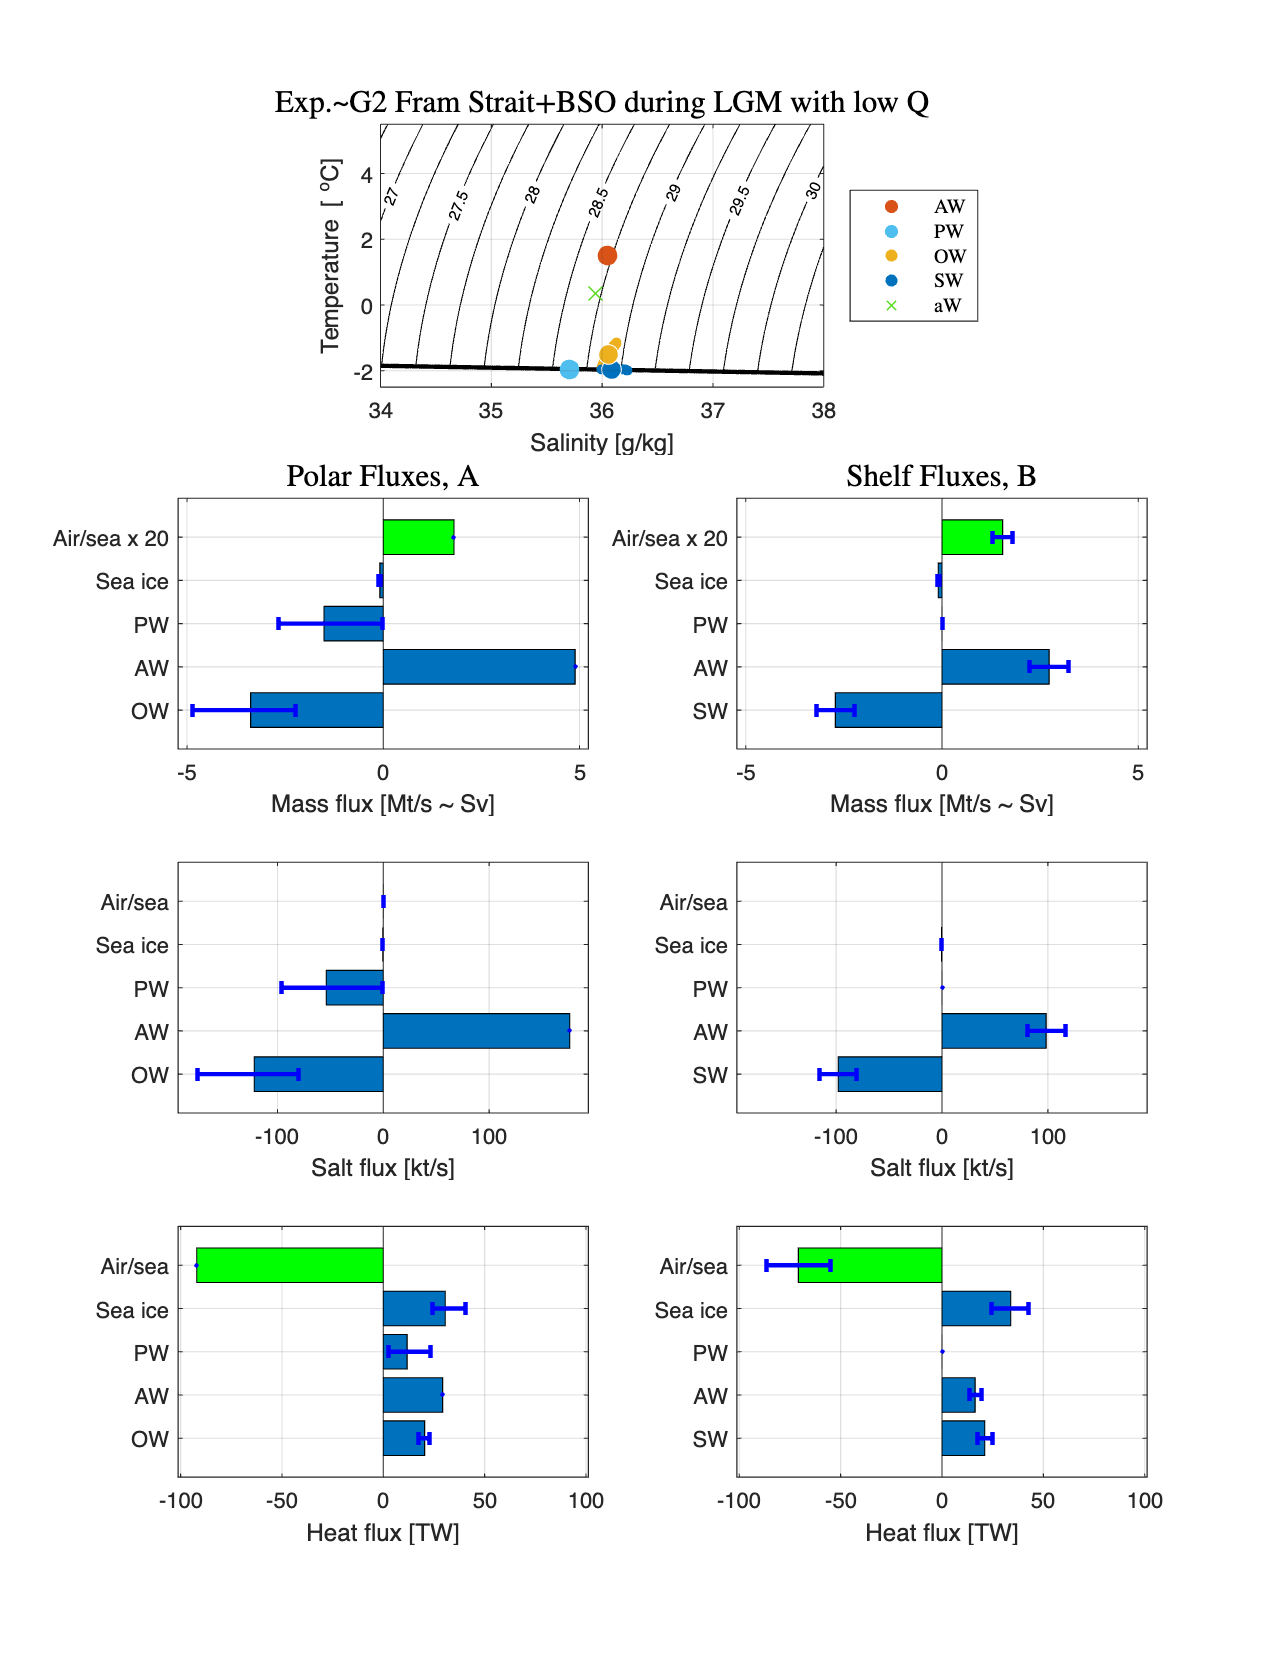

plot_POC_solution(modelG2)

modelG2 = build_stable_isotope_model(modelG2) ;

 Stable isotope solutions for experiment: [Exp.~G2 Fram Strait+BSO during LGM with low Q] with file suffices: [NH_FSBSO_LGM_lowQ]:
 Heavy isotope = [18O], light isotope = [16O], isotope ratio = [delta 18 oxygen].

 Numerical Results:
                                  18O           |        delta 18O 
                                  [ppm]         |        [o/oo]
-----------------------------------------------------------------------------------------
 Atlantic Water:                2000.44         |          0.00
 Basin meteoric water:          1940.55         |        -30.00
 Shelf meteoric water:          1940.55         |        -30.00

 Polar    Water:           2000.15 to  2000.15  |     -0.15 to    -0.15          
 Overflow Water:           1999.02 to  1999.02  |     -0.71 to    -0.71          
 Sea ice:                  1998.70 to  1998.70  |     -0.87 to    -0.87           
 Shelf    Water:           1998.70 to  1998.70  |     -0.87 to    -0.87           

